# Robotics, Vision & Control 3e: for MATLAB

# Chapter 5: Navigation

Copyright 2022-2023 Peter Corke, Witold Jachimczyk, Remo Pillat

bdclose all    % close all Simulink models
close all      % close all figures
clear          % clear all workspace variables
format compact % compact printout  

## 5.1 Introduction to Reactive Navigation

### 5.1.1 Braitenberg Vehicles

sl_braitenberg
sim("sl_braitenberg");

### 5.1.2 Simple Automata

load house
whos floorplan

  Name             Size               Bytes  Class     Attributes

  floorplan      397x596            1892896  double              



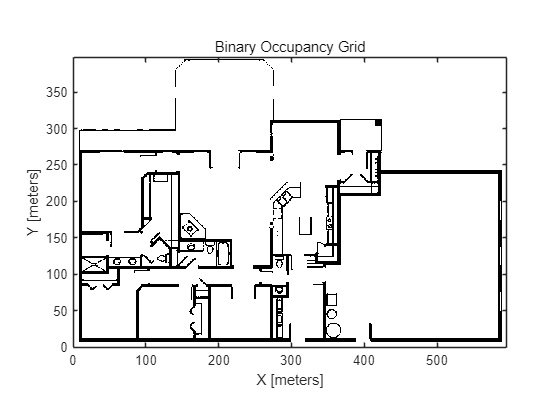

floorMap = binaryOccupancyMap(flipud(floorplan));
figure; floorMap.show

places

places = 包含以下字段的 struct :
     kitchen: [320 190]
      garage: [500 150]
         br1: [50 220]
         br2: [120 50]
         br3: [50 50]
        nook: [320 280]
     mudroom: [320 50]
       patio: [200 350]
       study: [220 50]
      garden: [100 350]
    driveway: [500 350]
      living: [220 200]

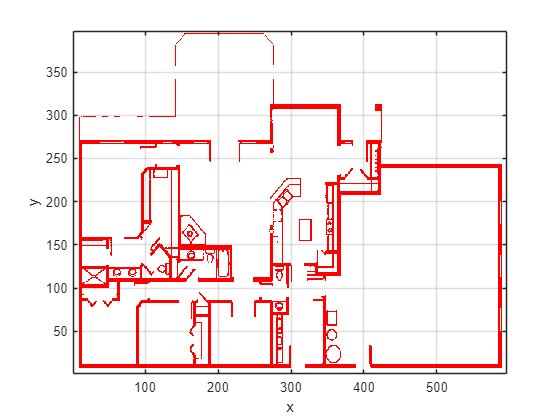

bug = Bug2(floorMap);
bug.plot

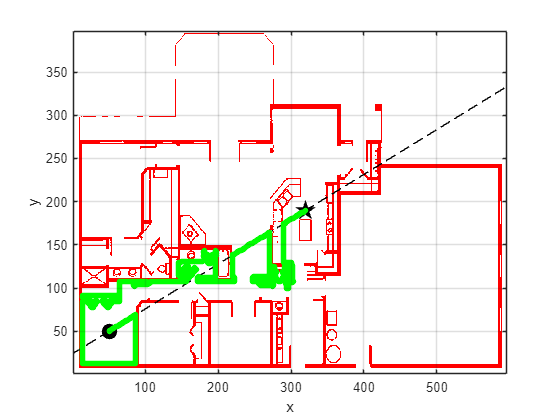

bug.run(places.br3,places.kitchen,animate=true);

p = bug.run(places.br3,places.kitchen);
whos p

  Name         Size            Bytes  Class     Attributes

  p         1300x2             20800  double              



## 5.3 Planning with a Graph-Based Map

data = jsondecode(fileread("queensland.json"))

data = 包含以下字段的 struct :
    places: [1×1 struct]
    routes: [29×1 struct]

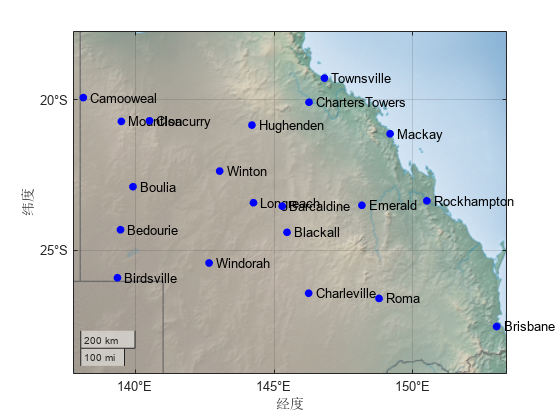

figure
geobasemap colorterrain
hold on
for p = string(fieldnames(data.places))'
  place = data.places.(p);
  geoplot(place.lat,place.lon,".b",MarkerSize=20)
  text(place.lat,place.lon+0.25,p)
end

data.routes(1)

ans = 包含以下字段的 struct :
       start: 'Camooweal'
         end: 'Mount Isa'
    distance: 188
       speed: 100

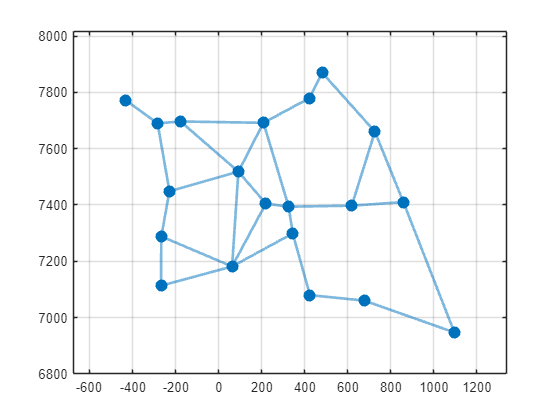

g = UGraph;
for name = string(fieldnames(data.places))'
  place = data.places.(name);
  g.add_node(place.utm,name=place.name);
end
for route = data.routes'
  g.add_edge(route.start,route.end,route.distance);
end
figure; g.plot;

g.n

ans = 20

g.ne

ans = 29

g.neighbors("Brisbane")

ans = 1×2 string 数组
    "Roma"    "Rockhampton"

nodeID = g.lookup("Brisbane")

nodeID = 1

g.neighbors(nodeID)

ans =     17    20


g.degree("Brisbane")

ans = 2

mean(g.degree)

ans = 2.9000

g.nc

ans = 1

e = g.edges("Brisbane")

e =      1     2


g.edgeinfo(e)

[Brisbane] -- [Roma], cost=482
[Brisbane] -- [Rockhampton], cost=682


### 5.3.1 Breadth-First Search

[pathNodes,pathLength] = g.path_BFS("Hughenden","Brisbane")

pathNodes = 1×5 string 数组
    "Hughenden"    "Barcaldine"    "Emerald"    "Rockhampton"    "Brisbane"

pathLength = 1759

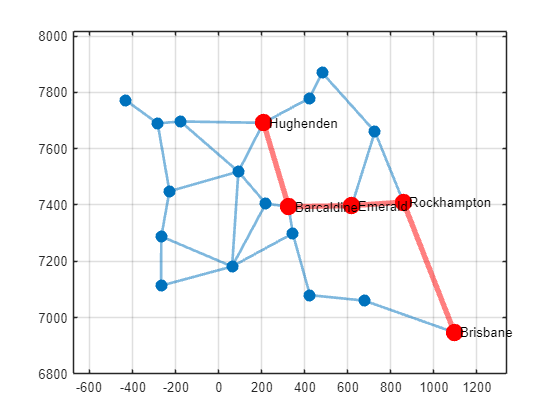

gPlot = g.plot;
g.highlight_path(gPlot,pathNodes,labels=true)

### 5.3.2 Uniform-Cost Search

[pathNodes,pathLength,searchTree] = ...
  g.path_UCS("Hughenden","Brisbane");
pathLength

pathLength = 1659

pathNodes

pathNodes = 1×6 string 数组
    "Hughenden"    "Barcaldine"    "Blackall"    "Charleville"    "Roma"    "Brisbane"

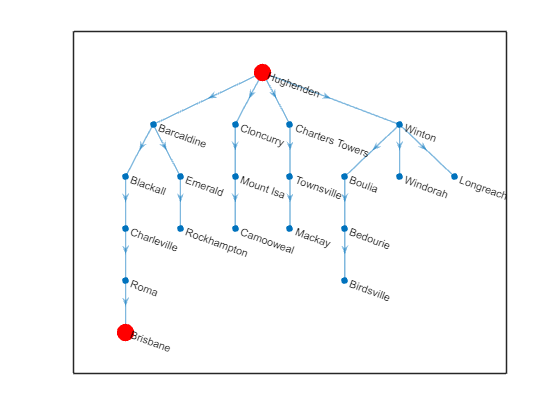

gPlot = searchTree.plot;
g.highlight_node(gPlot,["Hughenden","Brisbane"])

g.path_UCS("Hughenden","Brisbane",verbose=true)

FRONTIER: Hughenden(0)
EXPLORED: 
   expand Hughenden
   add Cloncurry to the frontier
   add Charters Towers to the frontier
   add Winton to the frontier
   add Barcaldine to the frontier
   move Hughenden to the explored list


FRONTIER: Winton(216), Charters Towers(248), Cloncurry(401), Barcaldine(500)
EXPLORED: Hughenden
   expand Winton
   add Boulia to the frontier
   add Windorah to the frontier
   add Longreach to the frontier
   move Winton to the explored list


FRONTIER: Charters Towers(248), Longreach(396), Cloncurry(401), Barcaldine(500), Boulia(579), Windorah(703)
EXPLORED: Hughenden, Winton
   expand Charters Towers
   add Townsville to the frontier
   move Charters Towers to the explored list


FRONTIER: Townsville(383), Longreach(396), Cloncurry(401), Barcaldine(500), Boulia(579), Windorah(703)
EXPLORED: Hughenden, Winton, Charters Towers
   expand Townsville
   add Mackay to the frontier
   move Townsville to the explored list


FRONTIER: Longreach(396), Cloncurry(40

ans = 1×6 string 数组
    "Hughenden"    "Barcaldine"    "Blackall"    "Charleville"    "Roma"    "Brisbane"

[~,costStartToBedourie] = g.path_UCS("Hughenden","Bedourie")

costStartToBedourie = 773

costBedourieToBirdsville = g.cost("Bedourie","Birdsville")

costBedourieToBirdsville = 193

### 5.3.3 A*

[pathNodes,pathLength,searchTree] = ...
  g.path_Astar("Hughenden","Brisbane",summary=true);

12 nodes explored, 3 remaining on the frontier


pathLength

pathLength = 1659

pathNodes

pathNodes = 1×6 string 数组
    "Hughenden"    "Barcaldine"    "Blackall"    "Charleville"    "Roma"    "Brisbane"

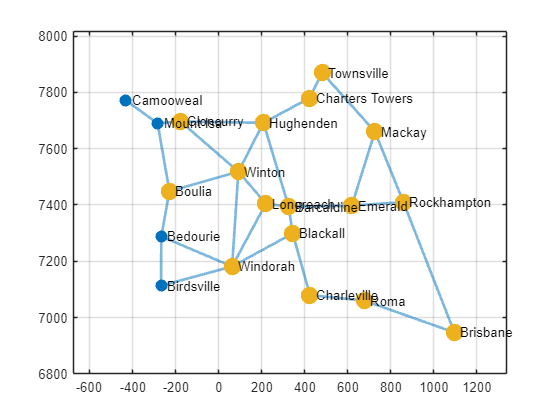

visitedNodes = string(searchTree.Nodes.Name);
gPlot = g.plot(labels=true);
g.highlight_node(gPlot,visitedNodes,NodeColor=[0.929 0.694 0.125])

g.path_Astar("Hughenden","Brisbane",verbose=true)

FRONTIER: Hughenden(0)
EXPLORED: 
   expand Hughenden
   add Cloncurry to the frontier
   add Charters Towers to the frontier
   add Winton to the frontier
   add Barcaldine to the frontier
   move Hughenden to the explored list


FRONTIER: Charters Towers(1318.9011), Winton(1371.2005), Barcaldine(1390.3419), Cloncurry(1878.2595)
EXPLORED: Hughenden
   expand Charters Towers
   add Townsville to the frontier
   move Charters Towers to the explored list


FRONTIER: Winton(1371.2005), Barcaldine(1390.3419), Townsville(1492.5933), Cloncurry(1878.2595)
EXPLORED: Hughenden, Charters Towers
   expand Winton
   add Boulia to the frontier
   add Windorah to the frontier
   add Longreach to the frontier
   move Winton to the explored list


FRONTIER: Longreach(1384.7038), Barcaldine(1390.3419), Townsville(1492.5933), Windorah(1762.3947), Cloncurry(1878.2595), Boulia(1995.0747)
EXPLORED: Hughenden, Charters Towers, Winton
   expand Longreach
   move Longreach to the explored list


FRONTIER: Bar

ans = 1×6 string 数组
    "Hughenden"    "Barcaldine"    "Blackall"    "Charleville"    "Roma"    "Brisbane"

### 5.3.4 Minimum-Time Path Planning

g = UGraph;
for name = string(fieldnames(data.places))'
  place = data.places.(name);
  g.add_node(place.utm,name=place.name);
end
for route = data.routes'
  g.add_edge(route.start,route.end,route.distance/route.speed);
end
g.measure = @(x1, x2) vecnorm(x1-x2)/100;
[pathNodes,time] = g.path_Astar("Hughenden","Brisbane")

pathNodes = 1×8 string 数组
    "Hughenden"    "Winton"    "Longreach"    "Barcaldine"    "Blackall"    "Charleville"    "Roma"    "Brisbane"

time = 16.6100

## 5.4 Planning with an Occupancy Grid Map

### 5.4.1 Distance Transform

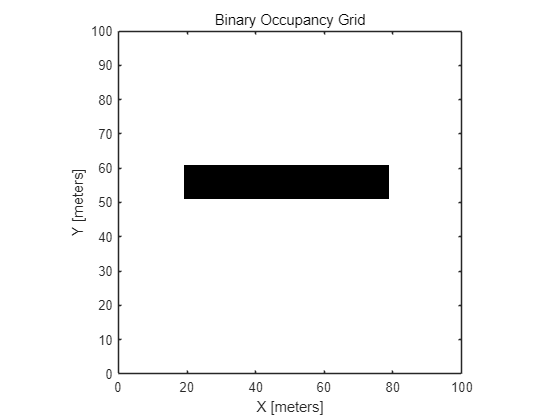

mapMatrix = false(100,100);
map = binaryOccupancyMap(mapMatrix);
map.setOccupancy([40 20], ...
  true(10,60), "grid");
map.show

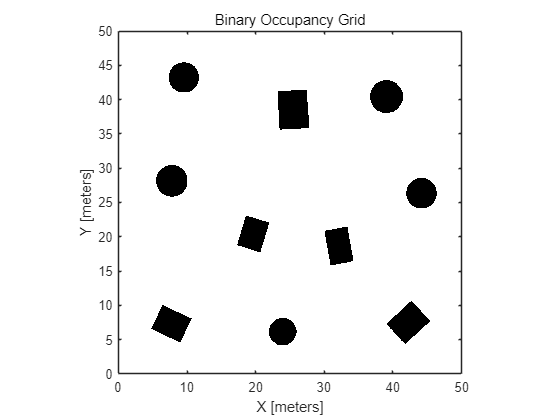

rng(0); % obtain repeatable results
map = mapClutter(10,["Box", ...
  "Circle"],MapResolution=20);
figure; map.show

simplegrid = binaryOccupancyMap(false(7,7));
simplegrid.setOccupancy([3 3],true(2,3),"grid");
simplegrid.setOccupancy([5 4],true(1,2),"grid");
dx = DistanceTransformPlanner(simplegrid)

dx = DistanceTransformPlanner navigation class:
  occupancy grid: 7x7                     
  distance metric: euclidean              
  distancemap: empty:                     

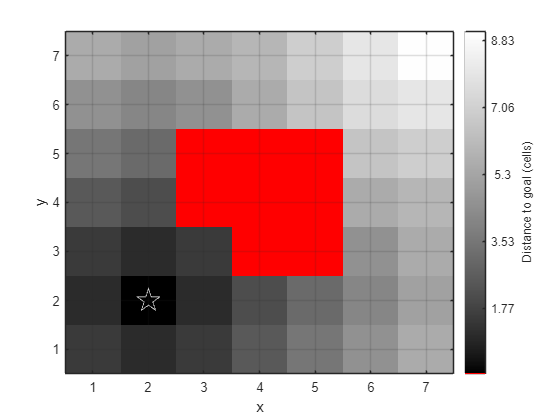

dx.plan([2 2])
dx.plot

dx = DistanceTransformPlanner(simplegrid,metric="manhattan");
dx.plan([2 2]);
pathPoints = dx.query([4 6])

pathPoints =      4     6
     3     6
     2     5
     2     4
     2     3
     2     2


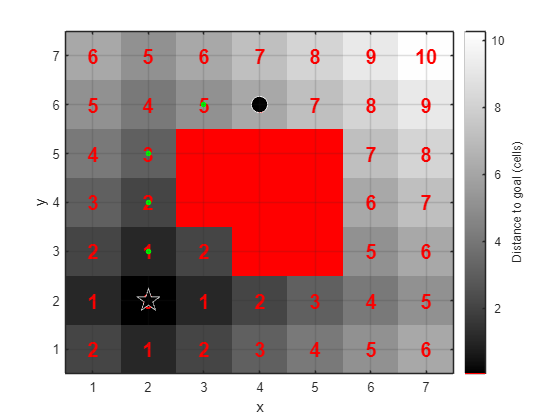

dx.plot(pathPoints,labelvalues=true)

pathPoints = dx.query([6 5])

pathPoints =      6     5
     6     4
     6     3
     5     2
     4     2
     3     2
     2     2


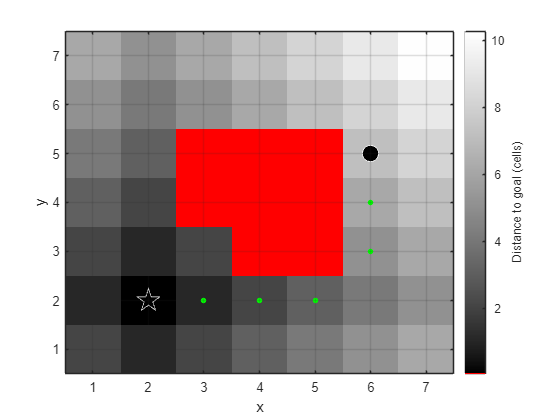

dx.plot(pathPoints)

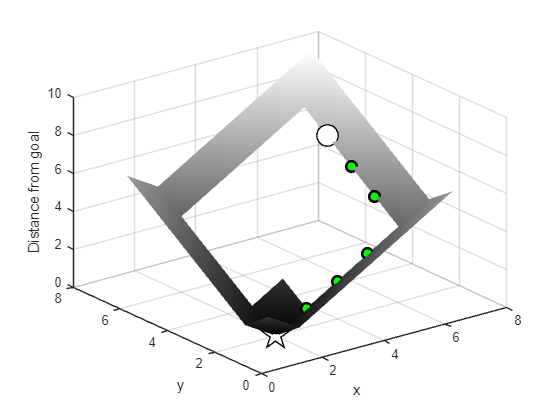

dx.plot3d(pathPoints)

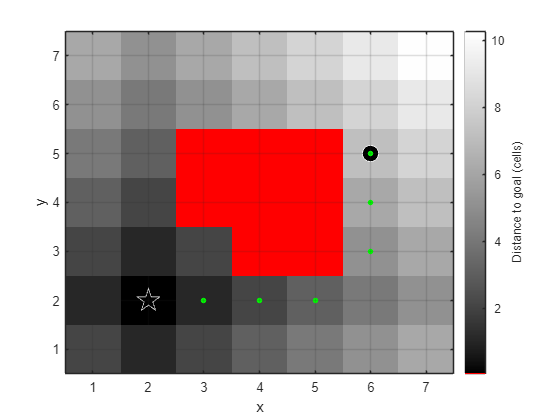

dx.query([6 5],animate=true)

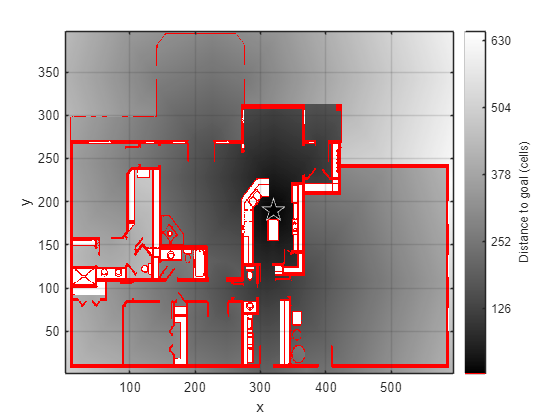

dx = DistanceTransformPlanner(floorplan);
dx.plan(places.kitchen)
dx.plot

pathPoints = dx.query(places.br3);
length(pathPoints)

ans = 338

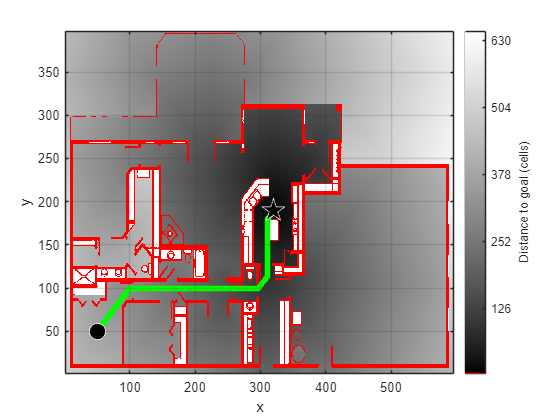

dx.plot(pathPoints);

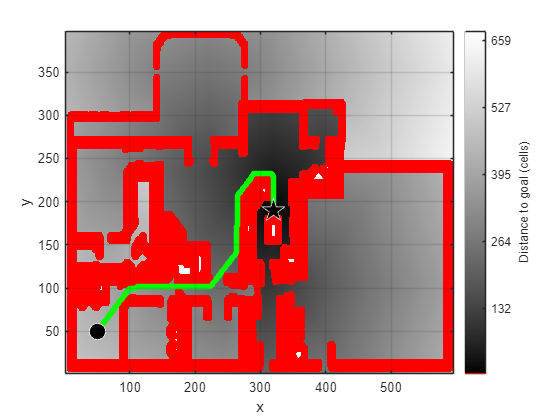

dx = DistanceTransformPlanner(floorMap,inflate=6);
dx.plan(places.kitchen);
pathPoints = dx.query(places.br3);
dx.plot(pathPoints,inflated=true);

### 5.4.2 D*

ds = DStarPlanner(floorMap);
c = ds.costmap;
ds.plan(places.kitchen)

245184 iterations


ds.niter

ans = 245184

ds.query(places.br3);
ds.modifyCost([290 335; 100 125],5);
ds.plan;

793198 iterations


ds.niter

ans = 793198

ds.query(places.br3);

## 5.5 Planning with Roadmaps

### 5.5.1 Introduction to Roadmap Methods

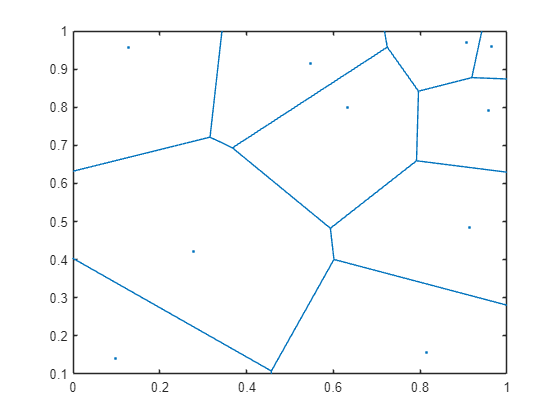

free = 1-floorplan;
free(1,:) = 0; free(end,:) = 0;
free(:,1) = 0; free(:,end) = 0;
skeleton = bwmorph(free,skel=Inf);
rng(0); % obtain repeatable results
sites = rand(10,2);
voronoi(sites(:,1),sites(:,2))

### 5.5.2 Probabilistic Roadmap Method (PRM)

rng(10) % obtain repeatable results
prm = mobileRobotPRM(floorMap)

prm =   mobileRobotPRM - 属性:

                   Map: [1×1 binaryOccupancyMap]
              NumNodes: 50
    ConnectionDistance: Inf

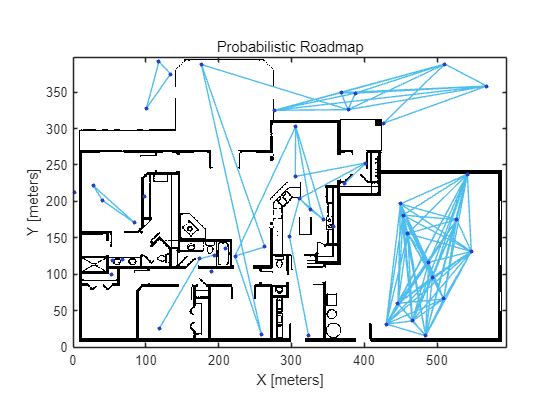

prm.show

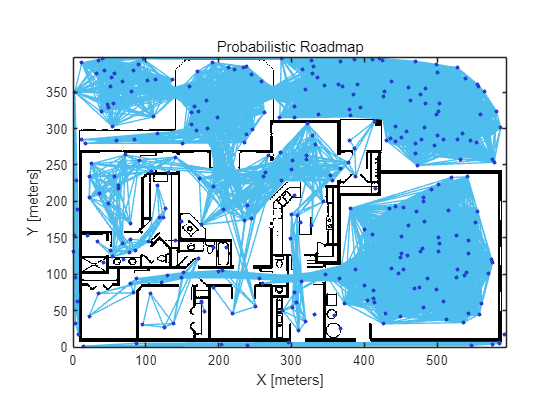

prm.NumNodes = 300;
prm.show;

rand

ans = 0.2935

rand

ans = 0.5543

rand

ans = 0.1897

rng("default")  % obtain repeatable results
rand

ans = 0.8147

rand

ans = 0.9058

p = prm.findpath(places.br3,places.kitchen)

p =    50.0000   50.0000
   35.1008   73.8081
  129.8734   98.8154
  313.9926   90.5135
  308.0064  180.9964
  320.0000  190.0000


## 5.6 Planning Drivable Paths

qs = [0 0 pi/2];
qg = [1 0 pi/2];

### 5.6.1 Dubins Path Planner

dubins = dubinsConnection(MinTurningRadius=1)

dubins =   dubinsConnection - 属性:

    DisabledPathTypes: {}
     MinTurningRadius: 1
         AllPathTypes: {'LSL'  'LSR'  'RSL'  'RSR'  'RLR'  'LRL'}

[paths,pathLength] = dubins.connect(qs,qg)

paths = 1×1 cell 数组
    {1×1 dubinsPathSegment}

pathLength = 7.2832

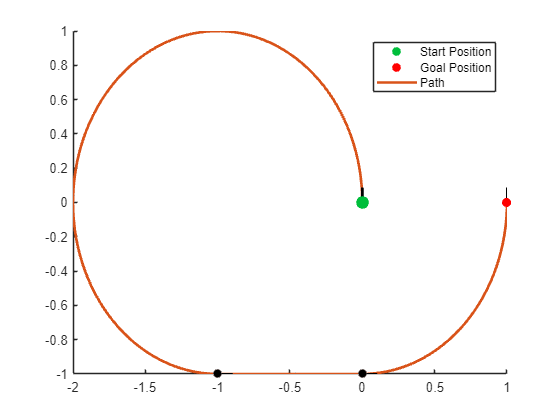

p = paths{1};
p.show

p

p =   dubinsPathSegment - 属性:

           StartPose: [0 0 1.5708]
            GoalPose: [1 0 1.5708]
    MinTurningRadius: 1
       MotionLengths: [4.7124 1 1.5708]
         MotionTypes: {'L'  'S'  'L'}
              Length: 7.2832

samples = p.interpolate(0:0.5:p.Length);
whos samples

  Name          Size            Bytes  Class     Attributes

  samples      18x3               432  double              



allTransPoints = p.interpolate;
samplesNoTrans = setdiff(samples,allTransPoints(2:end-1,:),"rows");
whos samplesNoTrans

  Name                 Size            Bytes  Class     Attributes

  samplesNoTrans      16x3               384  double              



### 5.6.2 Reeds-Shepp Path Planner

rs = reedsSheppConnection(MinTurningRadius=1);
[paths,pathLength] = rs.connect(qs,qg);
p = paths{1}

p =   reedsSheppPathSegment - 属性:

           StartPose: [0 0 1.5708]
            GoalPose: [1 0 1.5708]
    MinTurningRadius: 1
       MotionLengths: [0.5054 0.8128 0.8128 0.5054 0]
    MotionDirections: [1 -1 -1 1 1]
         MotionTypes: {'L'  'R'  'L'  'R'  'N'}
              Length: 2.6362

[samples,directions] = p.interpolate(0:0.3:p.Length)

samples =          0         0    1.5708
   -0.0447    0.2955    1.8708
   -0.1250    0.4841    2.0762
   -0.0753    0.4036    2.1708
    0.1284    0.1849    2.4708
    0.3876    0.0362    2.7708
    0.5000   -0.0000    2.8889
    0.6710   -0.0612    2.7070
    0.9203   -0.2261    2.4070
    1.1096   -0.4573    2.1070


directions =      1
     1
     1
    -1
    -1
    -1
    -1
    -1
    -1
    -1


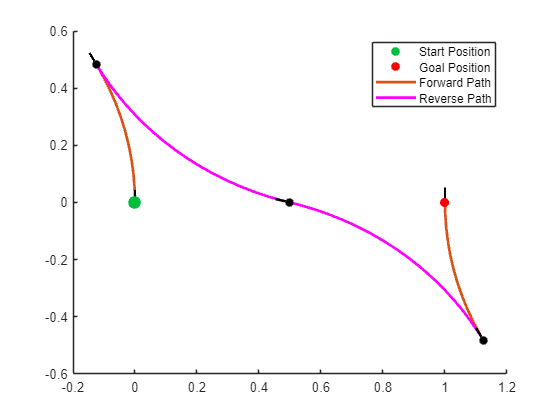

p.show

rs.ReverseCost = 3;
[paths,cost] = rs.connect(qs,qg);
p = paths{1}; 
cost

cost = 4.6577

p.Length

ans = 2.6362

[paths,pathLength] = rs.connect(qs,qg,PathSegments="all");
validPaths = find(~isnan(pathLength));
numel(validPaths)

ans = 8

### 5.6.3 Lattice Planner

lp = LatticePlanner;
lp.plan(iterations=1)

4 nodes created


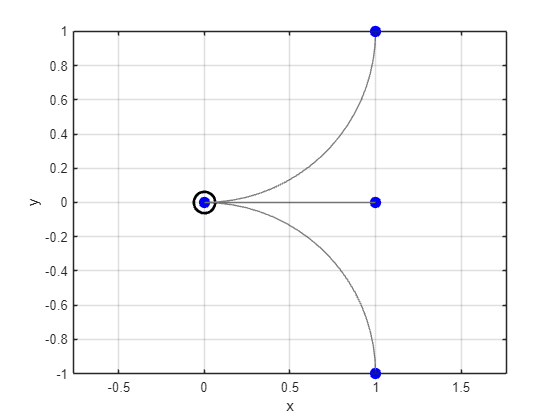

lp.plot

lp.plan(iterations=2)

13 nodes created


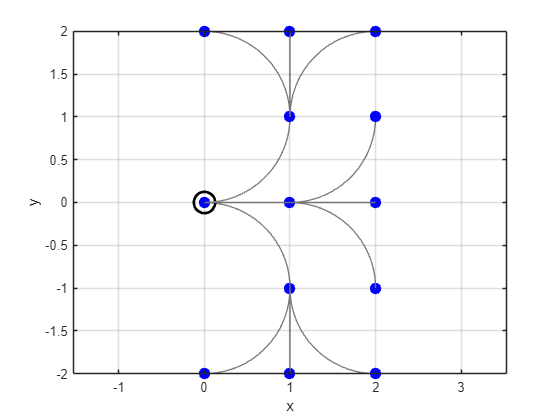

lp.plot

lp.plan(iterations=8)

780 nodes created


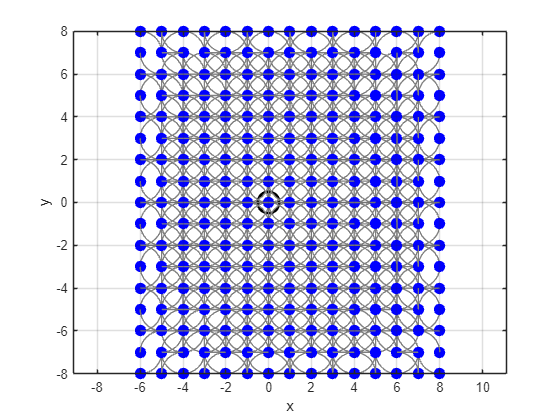

lp.plot

p = lp.query(qs,qg)

A* path cost 5


p =          0         0    1.5708
   -1.0000    1.0000    3.1416
   -2.0000         0   -1.5708
   -1.0000   -1.0000         0
         0   -1.0000         0
    1.0000         0    1.5708


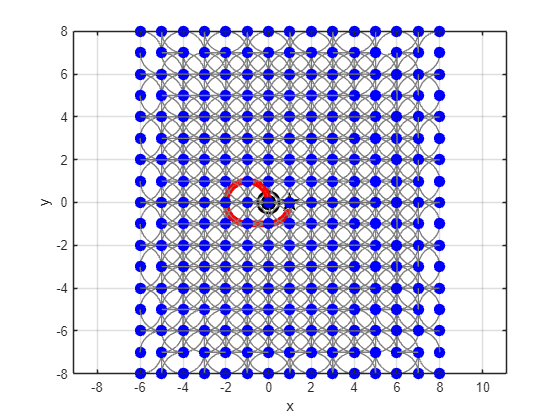

lp.plot

lp.plan(cost=[1 10 1]); % S, L, R

780 nodes created


lp.query(qs,qg);

A* path cost 5


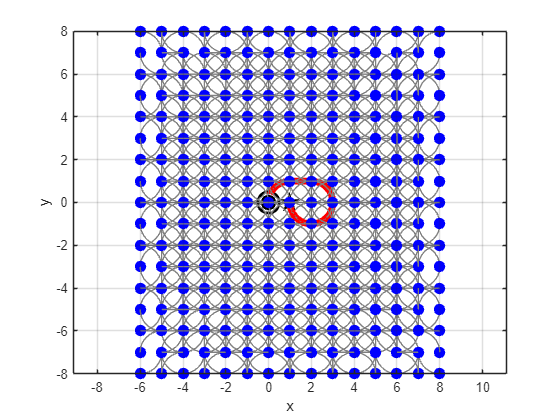

lp.plot

og = binaryOccupancyMap(false(11,11), ...
  GridOriginInLocal=[-5.5 -5.5]);
og.setOccupancy([-2.5 -2.5],true(1,5));
og.setOccupancy([-2.5 -1.5],true(1,3));
og.setOccupancy([1.5 -0.5],true(5,2));
lp = LatticePlanner(og);
lp.plan

355 nodes created


lp.query(qs,qg)

A* path cost 13


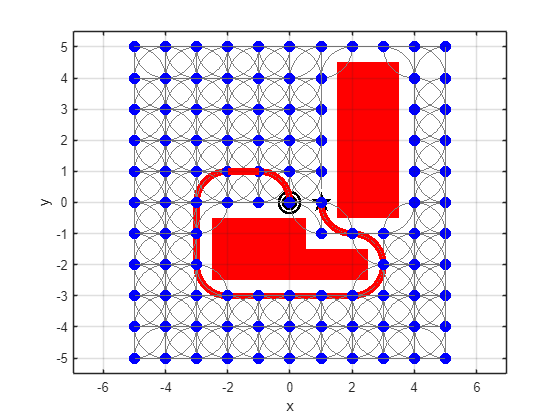

lp.plot

### 5.6.4 Clothoids

p = referencePathFrenet([qs;qg])

p =   referencePathFrenet - 属性:

                PathLength: 1.2743
         SegmentParameters: [0 0 1.5708 -7.2116 11.3186 0]
    DiscretizationDistance: 0.0500
                 Waypoints: [2×3 double]
           MaxNumWaypoints: Inf

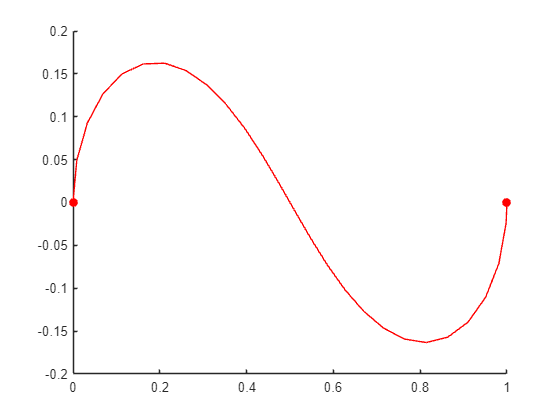

p.show;

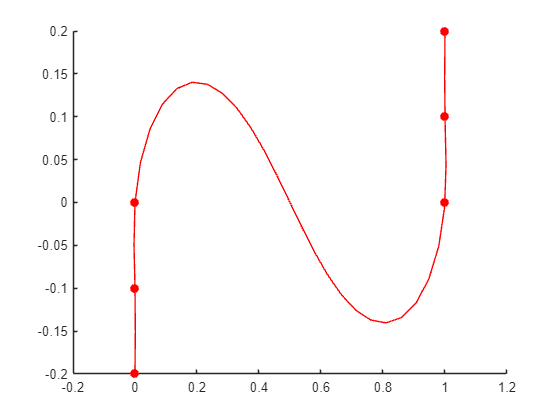

p = referencePathFrenet([0 -0.2; 0 -0.1; qs(1:2); ...
  qg(1:2); 1 0.1; 1 0.2]);
p.show;

%openExample("autonomous_control/" + ...
%  "HighwayTrajectoryPlanningUsingFrenetReferencePathExample");

### 5.6.5 Planning in Configuration Space (RRT)

bike = mobileRobotPropagator(KinematicModel="bicycle");
bike.SystemParameters.KinematicModel

ans = 包含以下字段的 struct :
     WheelBase: 1
    SpeedLimit: [-1 1]
    SteerLimit: [-0.7854 0.7854]

bike.SystemParameters.KinematicModel.SteerLimit = [-0.5 0.5];
bike.SystemParameters.KinematicModel.SpeedLimit = [0 1];
rrt = plannerControlRRT(bike)

rrt =   plannerControlRRT - 属性:

             StatePropagator: [1×1 mobileRobotPropagator]
    ContinueAfterGoalReached: 0
             MaxPlanningTime: Inf
              MaxNumTreeNode: 10000
             MaxNumIteration: 10000
            NumGoalExtension: 1
                    GoalBias: 0.1000
              GoalReachedFcn: @plannerControlRRT.GoalReachedDefault

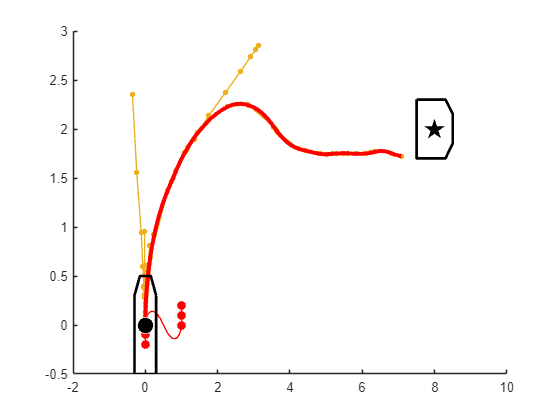

start = [0 0 pi/2];
goal = [8 2 0];
rng(0); % obtain repeatable results
[p,solnInfo] = rrt.plan(start,goal);
showControlRRT(p,solnInfo,[],start,goal); % [] for no map

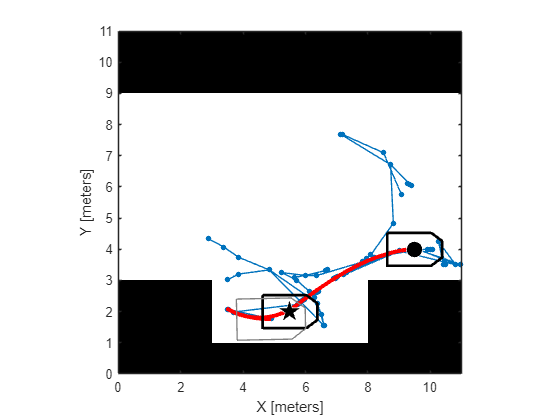

load parkingMap
inflatedMap = parkingMap.copy;
inflatedMap.inflate(0.5,"world");
carModel = mobileRobotPropagator( ...
  KinematicModel="bicycle",DistanceEstimator="reedsshepp", ...
  ControlPolicy="linearpursuit",Environment=inflatedMap);
carModel.SystemParameters.KinematicModel.WheelBase = 2;
carModel.StateSpace.StateBounds(1:2,:) = ...
  [parkingMap.XWorldLimits; parkingMap.YWorldLimits];
carModel.ControlStepSize = 0.1;
carModel.MaxControlSteps = 50;
rrt = plannerControlRRT(carModel);
rrt.NumGoalExtension = 2;
rrt.GoalReachedFcn = @(planner,q,qTgt) ...
  abs(angdiff(q(3),qTgt(3))) < 0.25 && ...
  norm(q(1:2)-qTgt(1:2)) < 0.75;
start = [9.5 4 0];
goal = [5.5 2 0];
rng(0); % obtain repeatable results
[p,solnInfo] = rrt.plan(start,goal);
showControlRRT(p,solnInfo,parkingMap,start,goal);
plotPath = p.copy; plotPath.interpolate;
plotvehicle(plotPath.States,"box",scale=1/20, ...
  edgecolor=[0.5 0.5 0.5],linewidth=1)

%openExample("nav/" + ...
%  "TractorTrailerPlanningUsingPlannerControlRRTExample");

## 5.7 Advanced Topics

### 5.7.3 Converting Between Graphs and Matrices

g = UGraph;
for i = 1:4 % add 4 nodes
  g.add_node([0 0]);
end
g.add_edge(1,2,1); % Connect nodes 1 and 2 with cost 1
g.add_edge(1,4,2); % Connect nodes 1 and 4 with cost 2
g.add_edge(2,3,3); % Connect nodes 2 and 3 with cost 3
D = g.adjacency

D =      0     1     0     2
     1     0     3     0
     0     3     0     0
     2     0     0     0


Suppress syntax warnings in this file

%#ok<*NASGU>
%#ok<*ASGLU>